# Probability of detection

clear                                  % Clear all data stored in variables
Am = 1;                                % 1V Amplitude     
SR = 48000;                            % 48 KHz Smapling Rate
f0 = 13e+3;                            % 20 KHz
duration = (127/SR);                   % ~ 2.6 ms 
t = 0:1/SR:duration;                   % Time Vector

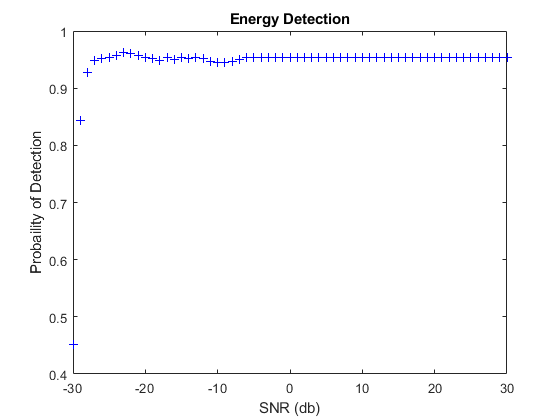

sinusPulse = Am*sin(2*pi*f0*t); 
mySNR = -30:1:30;           % SNR buffer
threshold = 30e5;
detectProbability(sinusPulse,mySNR,threshold)

function detectProbability(yourSignal,snr,threshold) 
    N = length(yourSignal);
    for i = 1:length(snr)
        Pd_buff(100) = 0;
        for j = 1:100
            a(N) = 0;
            yourSignal = awgn(yourSignal,snr(i));
            a(1) = abs(yourSignal(1)).^2;    
            for k = 2:N
                a(k) = a(k-1) + abs(yourSignal(k)).^2;
            end
            Pd_buff(j) = sum(a > threshold)/N;
        end
        Pd = sum(Pd_buff)/100;     
        plot(snr(i),Pd,'b+');
        hold on
        title('Energy Detection')
        xlabel('SNR (db)')
        ylabel('Probaility of Detection')
    end
    hold off
end